# **Kurvelineær (Krum) bevægelse**

**X-Y**

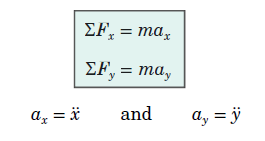

N-T

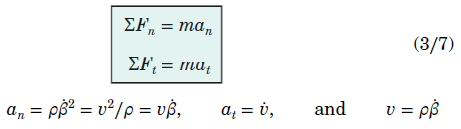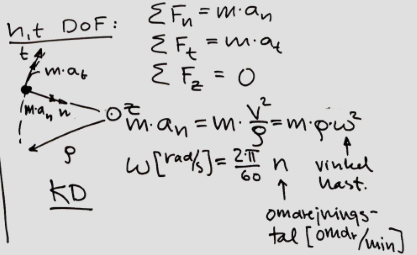

r-theta

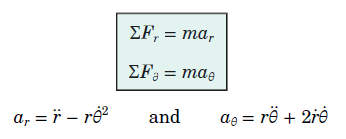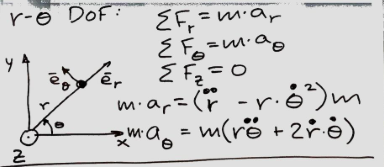


$$m\cdot a_n = m \cdot \frac{v^2}{\rho} = m\cdot \rho\cdot\omega^2$$


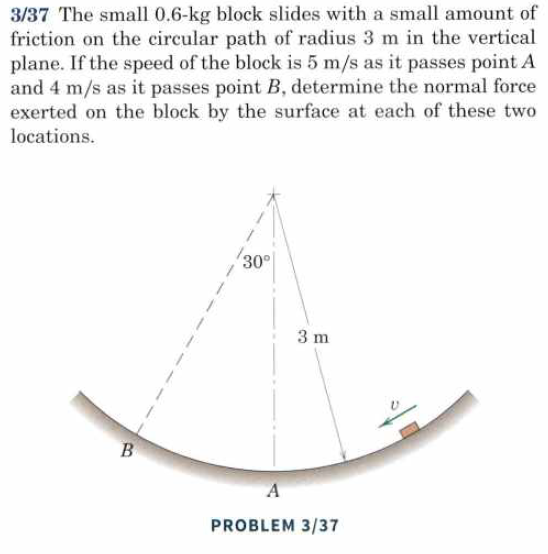

clear

displayFormula("F = m*a_n = m*v^2/rho")

$$\left(F=m\,a_{n}\right)=\frac{m\,v^{2}}{\rho }$$

displayFormula("N_A - m*g = m*v^2/rho")

$$N_{A}-m\,g=\frac{m\,v^{2}}{\rho }$$



m = 0.6;
rho = 3;
theta = deg2rad(30);
vA = 5;
vB = 4;
g = 9.81;


syms N_A
F = N_A - m*g == m*vA^2/rho;
N_A = vpa(solve(F, N_A),3)

$$N\_A = 10.9$$


$$N_A = 10.9 N$$


syms N_B
F = N_B - m*g*cos(theta) == m*vB^2/rho;
N_B = vpa(solve(F, N_B),3)

$$N\_B = 8.3$$


$$N_B = 8.3 N$$


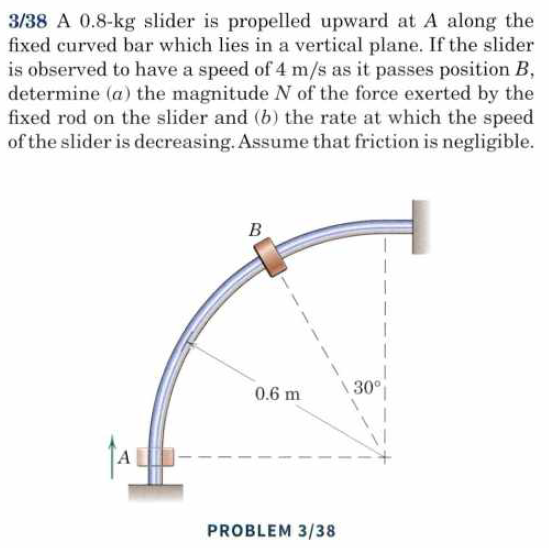

clear

displayFormula("F_A - m*g = m*v^2/rho")

$$F_{A}-m\,g=\frac{m\,v^{2}}{\rho }$$


m = 0.8;
rho = 0.6;
theta = deg2rad(30);
vB = 4;
g = -9.81;


syms F_A
Ft = F_A - m*g*cos(theta) == m*vB^2/rho;

F_A = vpa(solve(Ft, F_A),4)

$$F\_A = 14.54$$


syms a_t
Ft = m*a_t == m*g*sin(theta);

a_t = vpa(solve(Ft, a_t))

$$a\_t = -4.905$$


$$a_t = -4.905 m/s^2$$


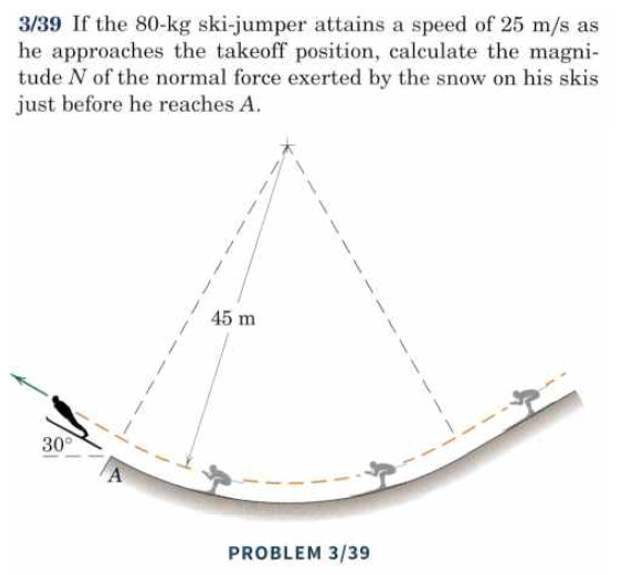

clear

m = 80;
rho = 45;
theta = deg2rad(30);
vA = 25;
g = -9.81;



syms N_A
F = N_A + m*g*cos(theta) == m*vA^2/rho;
N_A = vpa(solve(F, N_A),4)

$$N\_A = 1791.0$$

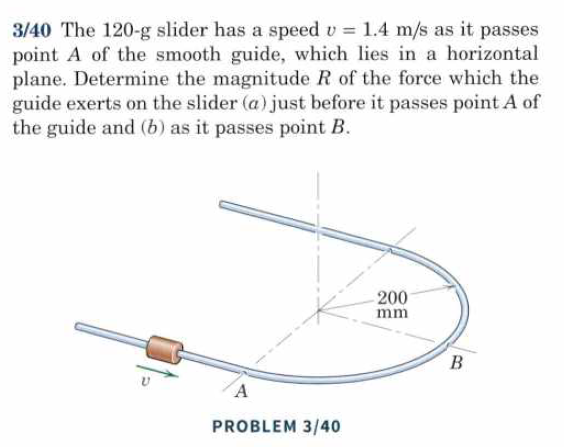

clear

g = -9.81;
m = 0.12;
rho = 0.2;
vA = 1.4;

% a) 
N_A = -m*g

N_A =        1.1772




% b)

N_B = m*vA^2/rho;
N_B = vpa(N_B,4)

$$N\_B = 1.176$$


R_B = sqrt(N_B^2 + N_A^2)

$$R\_B = 1.6639638938386757751364943682493$$

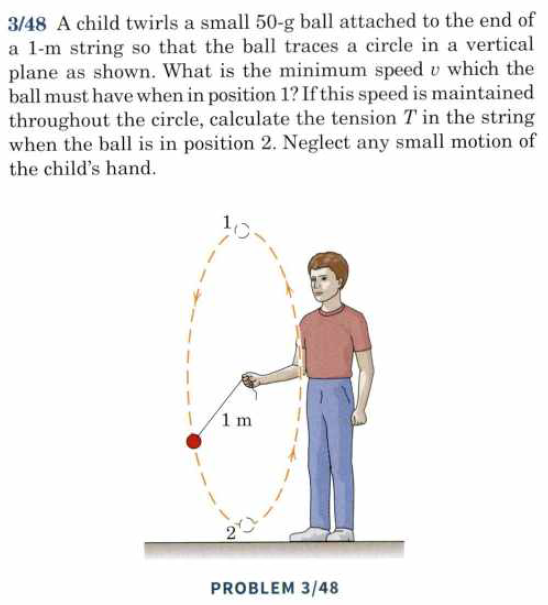

clear

g = 9.81;
m = 0.05;
rho = 1;

syms v
Fn = m*g == m*v^2*rho;

v = max(solve(Fn, v));
v = vpa(v, 4) 

$$v = 3.132$$


syms T
Fy = T - m*g == m*v^2*rho;

T = vpa(solve(Fy, T),3)

$$T = 0.981$$

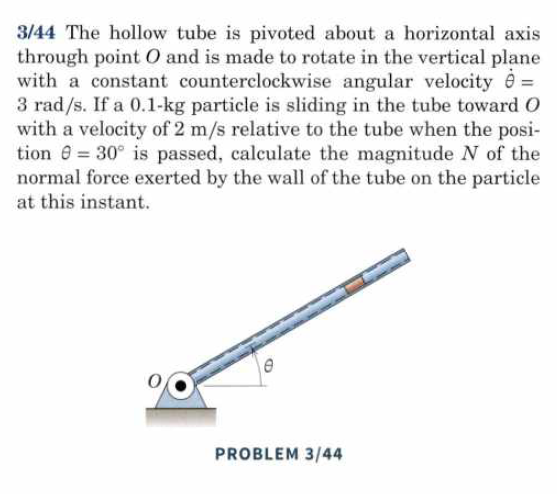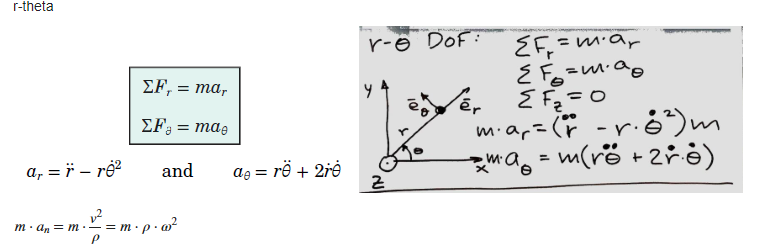

clear

g = 9.81;
% Partikel
m = 0.1;
vp = -2; % r_dot - nedadgående hastighed

% Vinkel til arm
theta = deg2rad(30);
theta1 = 3; % CCW
theta2 = 0; % theta1 er konstant

syms N
a_theta = 0 + 2*vp*theta1;
Ftheta = N - m*g*cos(theta) == m*a_theta;

N = vpa(solve(Ftheta, N), 3)

$$N = -0.35$$